%%%%%%%%%% 
% Had error in how threshold was being computed and applied to the confusion matrix
% It didnt make sense that reconstruction error was so high for the overall detection of anomalies
% to be so low. 
%%%%%%%%%%
% Compute Reconstruction Errors (MSE)
mseHealthy = mean((testHealthyData - predictedHealthy).^2,2);
mseAnomalous = mean((testAnomalousData - predictedAnomalous).^2,2);

% Compute Statistical Ranges
minErrorAnomalous = min(mseAnomalous);

% Classify Normal vs. Anomalous
predictedNormal = mseHealthy >= minErrorAnomalous;  
predictedAbnormal = mseAnomalous >= minErrorAnomalous;  


% True labels: 0 for normal, 1 for anomaly
trueLabels = [zeros(size(mseHealthy)); ones(size(mseAnomalous))];
trueLabels= logical(trueLabels)

trueLabels = 60×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


% Predicted labels
predictedLabels = [predictedNormal; predictedAbnormal];

% Generate confusion matrix
confMat = confusionmat(trueLabels, predictedLabels);

% Display confusion matrix
disp("Confusion Matrix:");

Confusion Matrix:


disp(confMat);

    30     0
     0    30



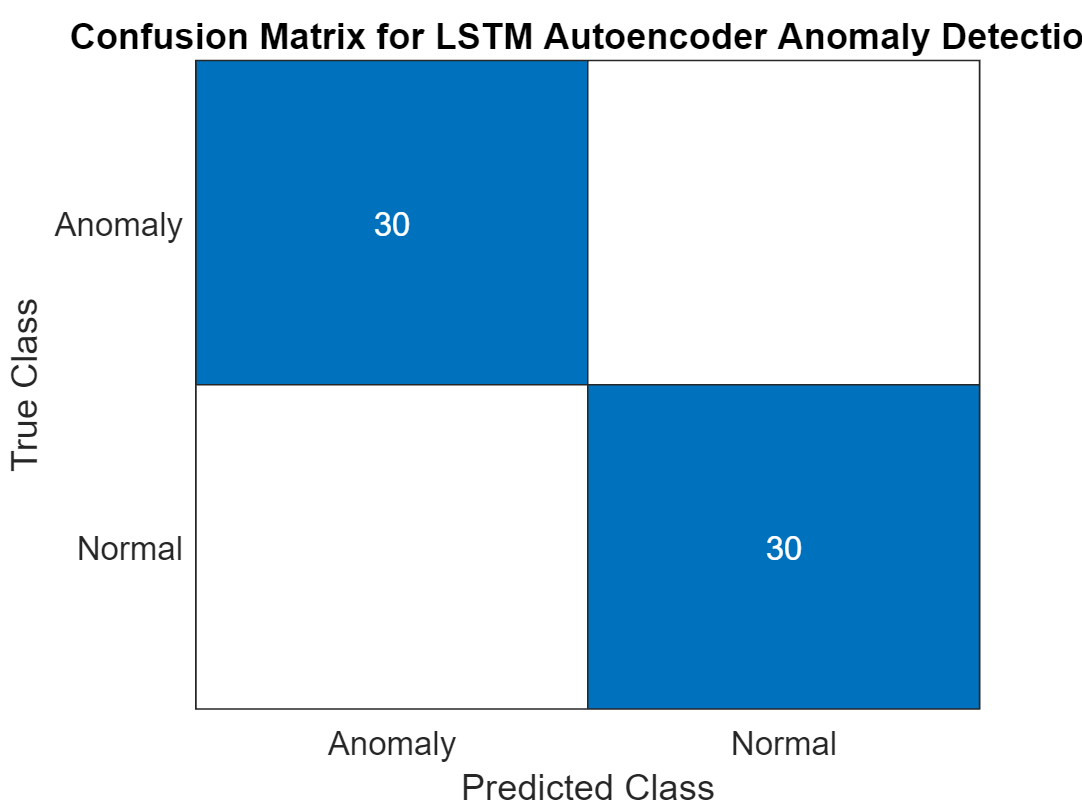


% Plot confusion matrix
figure;
confusionchart(confMat, {'Normal', 'Anomaly'});
title("Confusion Matrix for LSTM Autoencoder Anomaly Detection");

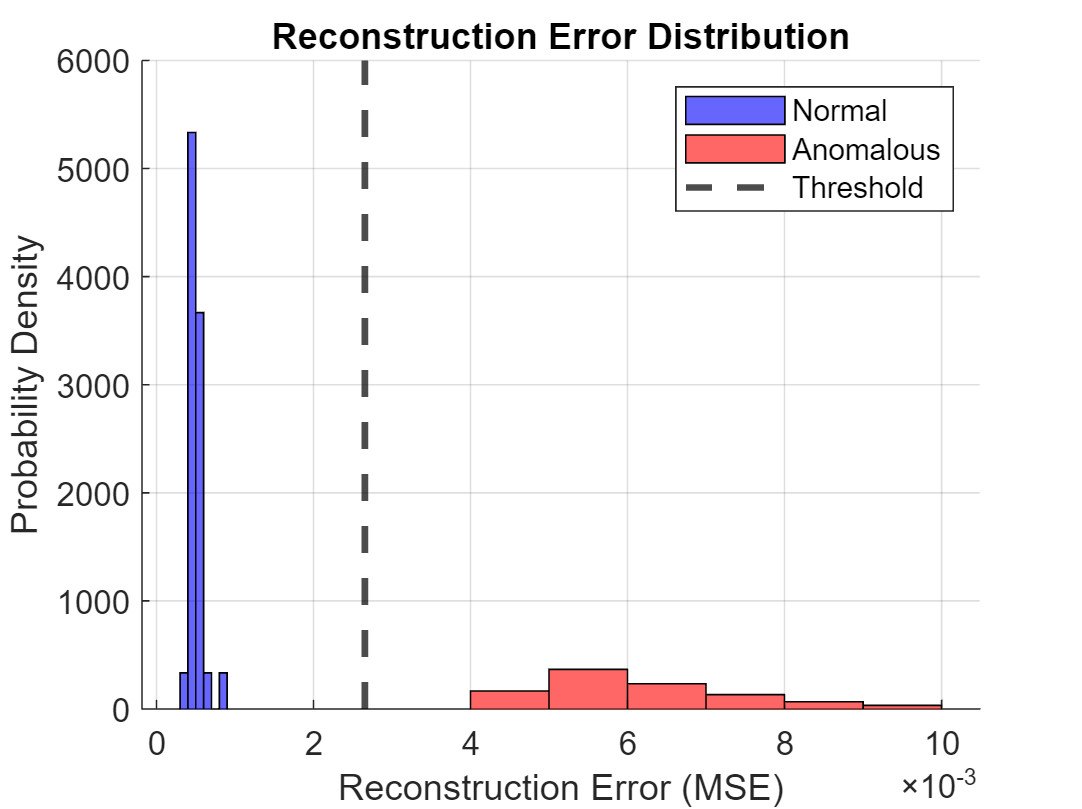


figure;
hold on;
histogram(mseHealthy, 'FaceColor', 'b', 'Normalization', 'pdf'); % Healthy Errors
histogram(mseAnomalous, 'FaceColor', 'r', 'Normalization', 'pdf'); % Anomalous Errors
xline(threshold, 'k--', 'LineWidth', 2); % Mark threshold
hold off;
title("Reconstruction Error Distribution");
xlabel("Reconstruction Error (MSE)");
ylabel("Probability Density");
legend("Normal", "Anomalous", "Threshold");
grid on;